# Create Animated 2-D Plots

`comet` plots an animation of a marker (head) and a line (tail) tracing a line growing over the data points. The tail is a solid line that traces the entire function.

## Create a function to Plot

Create a vector containing $x$ and $y$ values where $y$ is the evaluation of a sine function between 0 and $2\pi$, and  x is the evaluation of a cosine function between 0 and $2\pi \ldotp$ The $x$ and $y$ are solved over increments of $\pi /50$.  Increasing the increment size will cause the animation to execute faster and vice-versa.

t = 0:pi/20:2*pi;
y = sin(t);
x = cos(t);

### Animate the Plot

Passing the vectors $x$ and $y$ to the comet plot will animate the time-based parametric behavior.

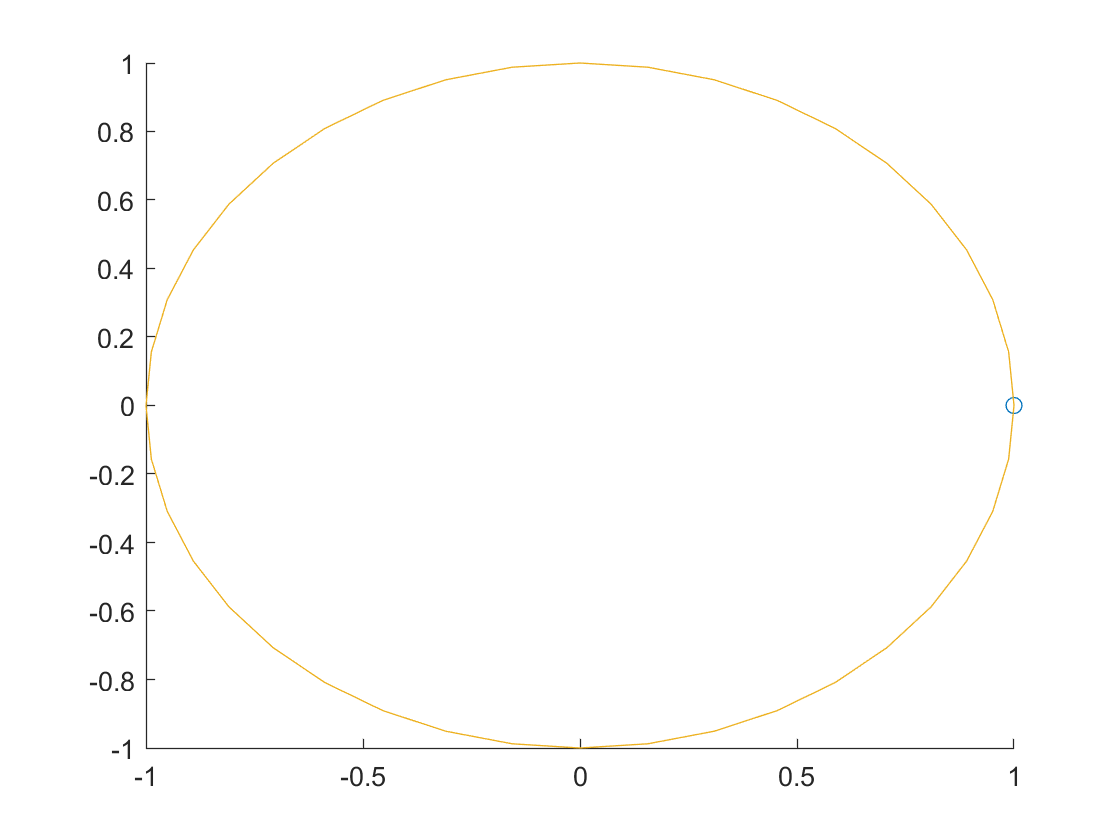

comet(x,y)

## Customizations

### Specify Animated Tail Length

Define the tail length as a percentage $p$ of the length of $y$. The default is set to 10%. Plot the animation by passing $x$, $y$, and $p$ to the `comet` function. 

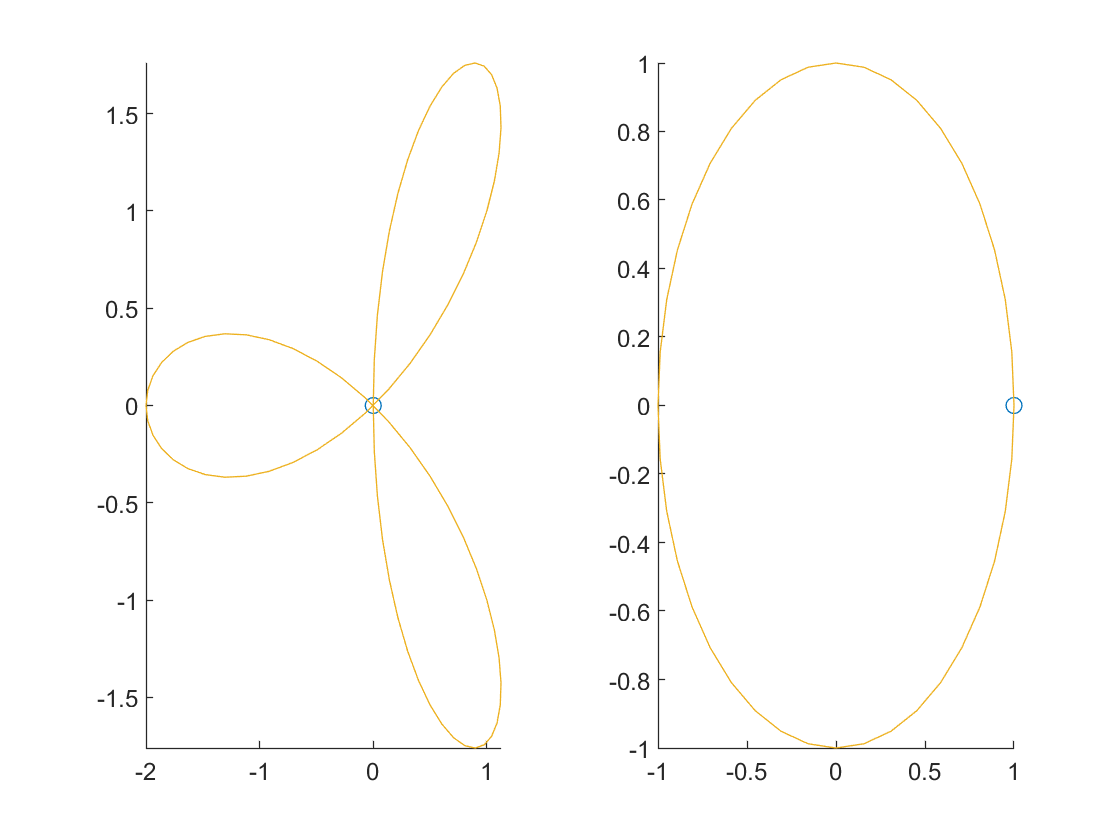

figure(1)
tailLength =0.65;
comet(x,y,...
    tailLength)                             % Specify the tail percentage length

### Add A Second Plot 

Create two comet plots in a tiled chart layout by specifying the target axes for each plot. Create two data sets, `x1` and `y1` and `x2` and `y2` as vectors of trigonometric functions with input values from 0 to $4\pi$. Specify the body length scale factor $p$ to be 25%

t = 0:pi/20:4*pi;
x1 = -cos(t) + cos(t/2);
y1 = -sin(t) - sin(t/2);
x2 =  cos(t) - cos(t/2);
y2 = -sin(t) - sin(t/2);
p = 0.25;

Store the two `Axes` objects as `ax1` and `ax2`. Specify the target axes for each comet plot by including the `Axes` object as the first input argument to `comet`.

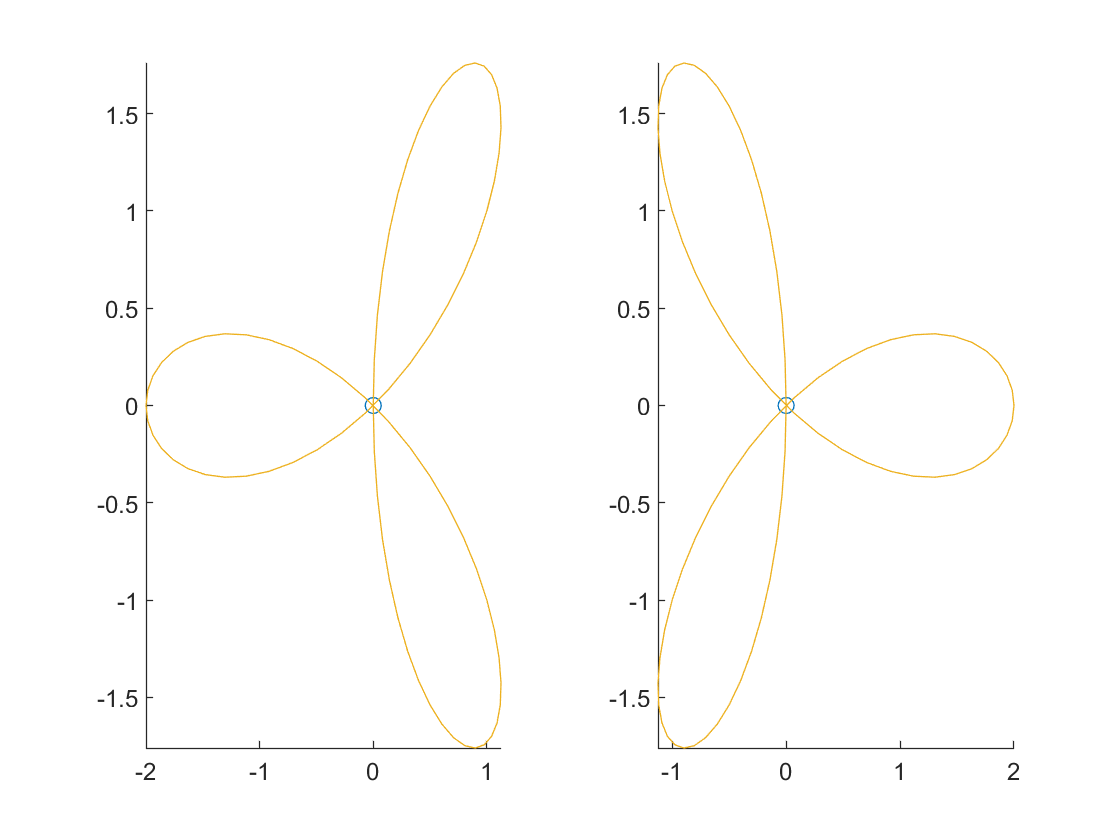

figure(2)
tiledlayout(1,2);
ax1 = nexttile;
ax2 = nexttile;

comet(ax1,x1,y1,p)
comet(ax2,x2,y2,p)

## Additional Information

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[comet](https://www.mathworks.com/help/matlab/ref/comet.html)